# LABORATOR 09

## P1

syms n
x = [0 : 5]';
y = [2.1 7.7 13.6 27.2 40.9 61.1]';

n = 2;
Z = [ones(size(x)) x x.^n];

b = (Z'*y);
a = (Z'*Z)\b;

fprintf("My coeffiecients:");

My coeffiecients:

disp(a);

   2.478571428571406
   2.359285714285740
   1.860714285714281



fprintf("MATLAB coefficients:")

MATLAB coefficients:

disp(flip(polyfit(x,y,n))');

   2.478571428571439
   2.359285714285706
   1.860714285714288




fprintf("Aproximanta discreta:");

Aproximanta discreta:

Sr = sum((y-Z*a).^2);
disp(Sr);

   3.746571428571435



## P2

close all
x=[-1.024940; -0.949898; -0.866114; -0.773392; -0.671372; -0.559524;...	
    -0.437067; -0.302909; -0.159493; -0.007464];
y=[-0.389269; -0.322894; -0.265256;	-0.216557;	-0.177152; -0.147582;...
    -0.128618; -0.121353;	-0.127348; -0.148895];

fprintf("Model elipsoidal pentru orbita");

Model elipsoidal pentru orbita

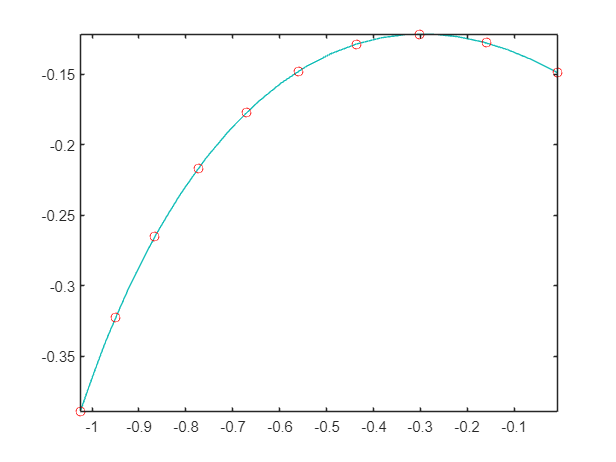

A=[y.^2, x.*y, x, y, ones(size(x))];
bv=x.^2;
coef=A\bv;
a=coef(1); b=coef(2); c=coef(3); d=coef(4); e=coef(5);

u=linspace(min(x),max(x),20);
v=linspace(min(y),max(y),20);
[X,Y]=meshgrid(u,v);
Z=a*Y.^2+b*X.*Y+c*X+d*Y+e-X.^2;
contour(X,Y,Z,[0,0]); hold on
plot(x,y,'ro'); hold on

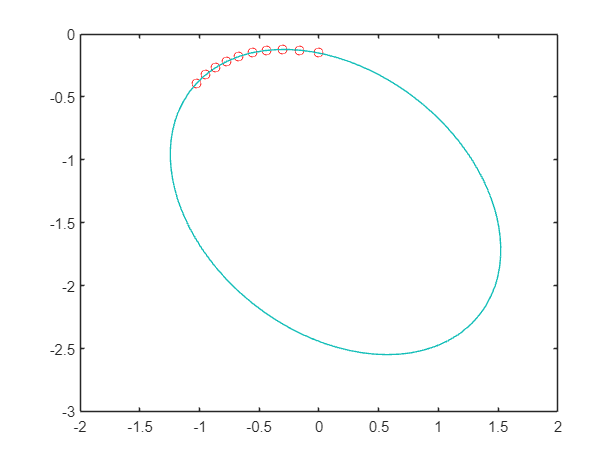


figure()
plot(x,y,'ro'); hold on
u=linspace(-2,2,40);
v=linspace(-3,0,40);
[X,Y]=meshgrid(u,v);
Z=a*Y.^2+b*X.*Y+c*X+d*Y+e-X.^2;
contour(X,Y,Z,[0,0]); 


err=sum((a*y.^2+b*x.*y+c*x+d*y+e-x.^2).^2).^(1/2)

err =    0.001098384364335


errb=norm(a*y.^2+b*x.*y+c*x+d*y+e-x.^2)

errb =    0.001098384364335


fprintf("Model parabolic pentru orbita");

Model parabolic pentru orbita

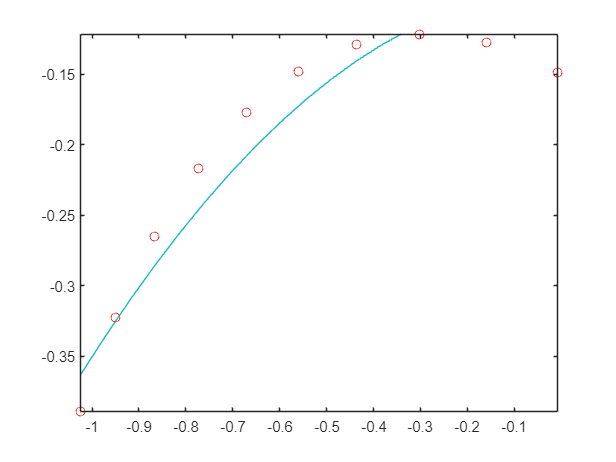

figure()
A2=[y,ones(size(x))];
coef2=A2\bv;
a=coef2(1); e=coef2(2);
u=linspace(min(x),max(x),20);
v=linspace(min(y),max(y),20);
[X,Y]=meshgrid(u,v);
Z=a*Y+e-X.^2;
contour(X,Y,Z,[0,0]); hold on
plot(x,y,'ro')

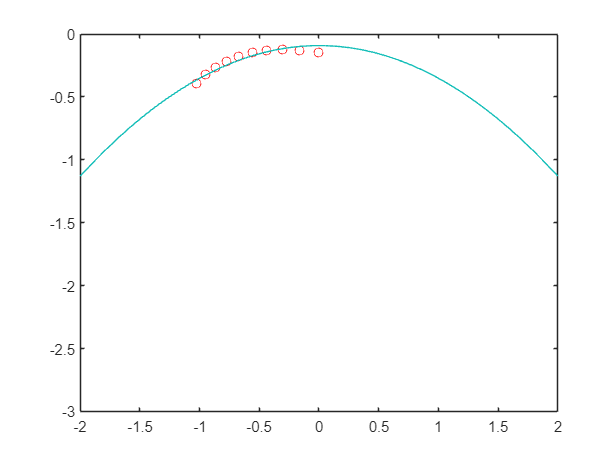

figure()
plot(x,y,'ro'); hold on
u=linspace(-2,2,40);
v=linspace(-3,0,40);
[X,Y]=meshgrid(u,v);
Z=a*Y+e-X.^2;
contour(X,Y,Z,[0,0]);


err2=sum((a*y+e-x.^2).^2)^(1/2)

err2 =    0.343340386341414


err2b=norm(a*y+e-x.^2)

err2b =    0.343340386341414


% Se observa ca modelul eliptic este mai probabil (are eroare mai mica)

## P3

A=[1	1	1
1	1	0
0	1	1
1	0	0
0	0	1];
b=[89
67
53
35
20];
x=A\b;
fprintf("x1 = %f\nx2 = %f\nx3 = %f",x(1),x(2),x(3));

x1 = 35.125000
x2 = 32.500000
x3 = 20.625000

## P4

clear all
%CENSUS - example with census data
%          polynomial fit

%population
y = [ 75.995  91.972 105.711 123.200 131.670 150.700 ...
    179.320 203.210 226.510 249.630 281.420 308.790]';

t = (1900:10:2010)';   % census years

x = (1890:1:2019)';    % evaluation years
w = [1975,2015];       % prediction years

c=polyfit(t,y,3)

c = 1.0e+04 *

  -0.000000000657317   0.000004765758684  -0.010884932365825   7.993352721944025


mt=mean(t); st=std(t);

s=(t-mt)/st;
xs=(x-mt)/st;

% normalizare

% coeficientii
cs=polyfit(s,y,3)

cs = 1.0e+02 *

  -0.003080986054546   0.118377467532468   0.765605837165184   1.664927321428570



% predictiile
zs=polyval(cs,xs);
est=polyval(cs,(w-mt)/st);

% grafic
hold off

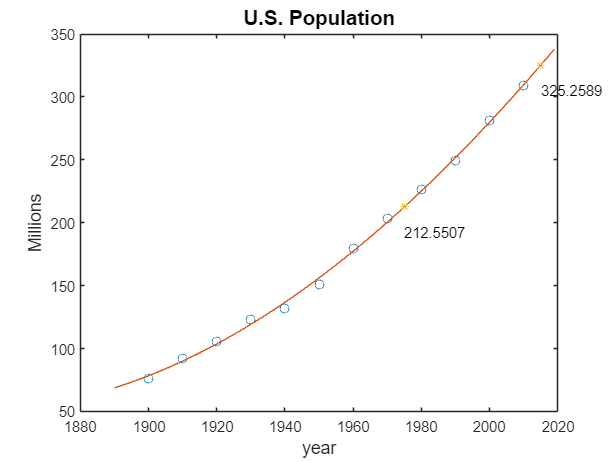

plot(t,y,'o',x,zs,'-',w,est,'*')
for i=1:length(w)
    text(w(i),est(i)-20,num2str(est(i)))
end
title('U.S. Population', 'FontSize', 14)
xlabel('year', 'FontSize', 12)
ylabel('Millions', 'FontSize', 12)

clear all
%CENSUS - example with census data
%          exponetial fit

%data
y = [ 75.995  91.972 105.711 123.200 131.670 150.700 ...
    179.320 203.210 226.510 249.630 281.420 308.790]';

t = (1900:10:2010)';   % census years

x = (1890:1:2019)';    % evaluation years
w = [1975,2015];              % prediction year

% coeficientii
cs=polyfit(t,log(y),1);
K=exp(cs(2)) 

K =      3.274275407095615e-09


lambda=cs(1)

lambda =    0.012595352981789



% predictii
fm=@(t) K*exp(lambda*t);
zs=fm(x);
est=fm(w);

% grafic
hold off

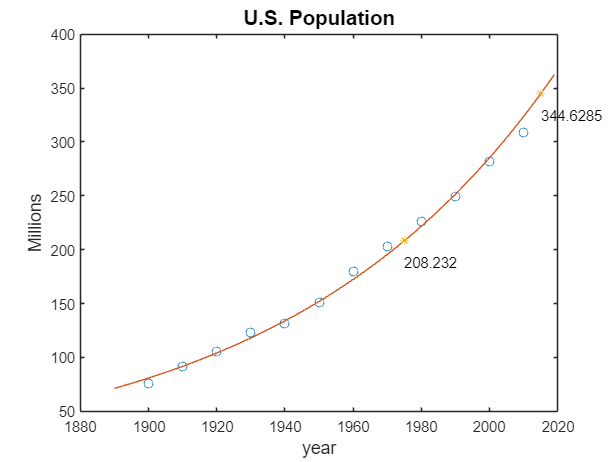

plot(t,y,'o',x,zs,'-',w,est,'*')
for i=1:length(w)
    text(w(i),est(i)-20,num2str(est(i)))
end
title('U.S. Population', 'FontSize', 14)
xlabel('year', 'FontSize', 12)
ylabel('Millions', 'FontSize', 12)